# Machine Learning

## Support Vector Machines

In this exercise, you will be using support vector machines (SVMs) to build a spam classifier. 

### Files needed for this exercise

- `home.mlx` - MATLAB Live Script that steps you through the exercises

#### **Part 2**

- `spamTrain.mat` - Spam training set

- `spamTest.mat` - Spam test set

- emailSample1.txt - Sample email 1

- emailSample2.txt - Sample email 2

- spamSample1.txt - Sample spam 1

- spamSample2.txt - Sample spam 2

- vocab.txt - Vocabulary list

- `getVocabList.m` - Load vocabulary list

- `porterStemmer.m` - Stemming function

- `readFile.m` - Reads a file into a character string

- `processEmail.m` - Email preprocessing

- `emailFeatures.m` - Feature extraction from emails

#### Confirm that your Current Folder is set correctly

Click into this section, then click the 'Run section' button above. This will execute the `dir` command below to list the files in your Current Folder. The output should contain all of the files listed above and the 'lib' folder. If it does not, right-click the 'ex6' folder and select 'Open' before proceding or see the instructions in `README.mlx` for more details.

dir

.                 emailSample1.txt  getVocabList.m    porterStemmer.m   spamSample2.txt   svmPredict.m      
..                emailSample2.txt  home.mlx          processEmail.m    spamTest.mat      svmTrain.m        
emailFeatures.m   gaussianKernel.m  linearKernel.m    spamSample1.txt   spamTrain.mat     vocab.txt         



## Spam Classification

Many email services today provide spam filters that are able to classify emails into spam and non-spam email with high accuracy. In this part of the exercise, you will use SVMs to build your own spam filter. You will be training a classifier to classify whether a given email, $x$, is spam ($y = 1$) or non-spam ($y = 0$). In particular, you need to convert each email into a feature vector $x\in\mathbb{R}^n$.

The dataset included for this exercise is based on a a subset of the [SpamAssassin Public Corpus](https://spamassassin.apache.org/old/publiccorpus/). For the purpose of this exercise, you will only be using the body of the email (excluding the email headers).

### Preprocessing emails

Before starting on a machine learning task, it is usually insightful to take a look at examples from the dataset. Figure 8 shows a sample email that contains a URL, an email address (at the end), numbers, and dollar amounts. While many emails would contain similar types of entities (e.g., numbers, other URLs, or other email addresses), the specific entities (e.g., the specic URL or specific dollar amount) will be different in almost every email.

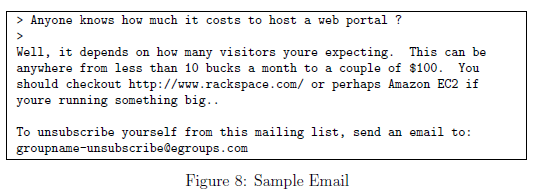

    Therefore, one method often employed in processing emails is to 'normalize' these values, so that all URLs are treated the same, all numbers are treated the same, etc. For example, we could replace each URL in the email with the unique string "httpaddr" to indicate that a URL was present. This has the effect of letting the spam classifier make a classification decision based on whether any URL was present, rather than whether a specific URL was present. This typically improves the performance of a spam classifier, since spammers often randomize the URLs, and thus the odds of seeing any particular URL again in a new piece of spam is very small.

    In `processEmail.m`, we have implemented the following email preprocessing and normalization steps:

- Lower-casing: The entire email is converted into lower case, so that captialization is ignored (e.g., IndIcaTE is treated the same as indicate).

- Stripping HTML: All HTML tags are removed from the emails. Many emails often come with HTML formatting; we remove all the HTML tags, so that only the content remains.

- Normalizing URLs: All URLs are replaced with the text "httpaddr".

- Normalizing Email Addresses: All email addresses are replaced with the text "emailaddr".

- Normalizing Numbers: All numbers are replaced with the text 'number'.

- Normalizing Dollars: All dollar signs ($) are replaced with the text 'dollar'.

- Word Stemming: Words are reduced to their stemmed form. For example, 'discount', 'discounts', 'discounted' and 'discounting' are all replaced with 'discount'. Sometimes, the Stemmer actually strips off additional characters from the end, so 'include', 'includes', 'included', and 'including' are all replaced with 'includ'.

- Removal of non-words: Non-words and punctuation have been removed. All white spaces (tabs, newlines, spaces) have all been trimmed to a single space character.

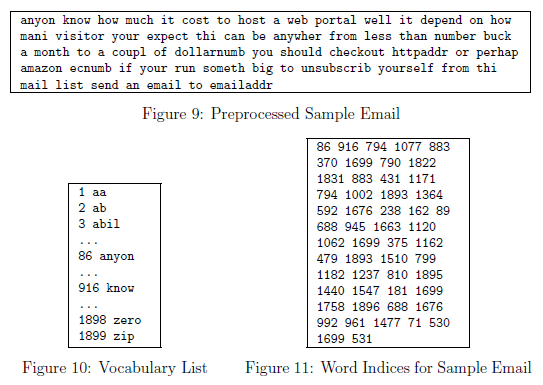

    The result of these preprocessing steps is shown in Figure 9. While preprocessing has left word fragments and non-words, this form turns out to be much easier to work with for performing feature extraction.

#### Vocabulary list

After preprocessing the emails, we have a list of words (e.g., Figure 9) for each email. The next step is to choose which words we would like to use in our classifier and which we would want to leave out. For this exercise, we have chosen only the most frequently occuring words as our set of words considered (the vocabulary list). Since words that occur rarely in the training set are only in a few emails, they might cause the model to overfit our training set. The complete vocabulary list is in the file vocab.txt and also shown in Figure 10. Our vocabulary list was selected by choosing all words which occur at least a 100 times in the spam corpus, resulting in a list of 1899 words. In practice, a vocabulary list with about 10,000 to 50,000 words is often used.

Given the vocabulary list, we can now map each word in the preprocessed emails (e.g., Figure 9) into a list of word indices that contains the index of the word in the vocabulary list. Figure 11 shows the mapping for the sample email. Specically, in the sample email, the word 'anyone' was first normalized to 'anyon' and then mapped onto the index 86 in the vocabulary list.

Once you have implemented `processEmail.m`, the code below will run your code on the email sample and you should see an output similar to Figures 9 & 11.

**MATLAB Tip**: In MATLAB, you can compare two strings with the `strcmp` function. For example, `strcmp(str1, str2)` will return 1 only when both strings are equal. In the provided starter code, `vocabList` is a 'cell-array' containing the words in the vocabulary. In MATLAB, a cell-array is just like a normal array (i.e., a vector), except that its elements can also be strings (which they can't in a normal MATLAB matrix/vector), and you index into them using curly braces instead of square brackets. Specically, to get the word at index `i`, you can use `vocabList{i}`. You can also use `length(vocabList)` to get the number of words in the vocabulary.

%% Initialization
clear;

% Extract Features
file_contents = readFile('emailSample1.txt');
word_indices  = processEmail(file_contents);
% Print Stats
disp(word_indices)

### Extracting features from emails

You will now implement the feature extraction that converts each email into a vector in $\mathbb{R}^n$. For this exercise, you will be using words in vocabulary list. Specically, the feature $x_i\in\{0,\;1\}$for an email corresponds to whether the $i$-th word in the dictionary occurs in the email. That is, $x_i = 1$ if the $i$-th word is in the email and $x_i = 0$ if the $i$-th word is not present in the email.

    Thus, for a typical email, this feature would look like:


$$x=\left\lbrack \begin{array}{c}
0\\
\vdots \\
1\\
0\\
\vdots \\
1\\
0\\
\vdots \\
0
\end{array}\right\rbrack \in R^n$$


You should now complete the code in `emailFeatures.m` to generate a feature vector for an email, given the word indices. Once you have implemented `emailFeatures.m`, the code below will will run your code on the email sample. You should see that the feature vector had length 1899 and 45 non-zero entries.

% Extract Features
features = emailFeatures(word_indices);

% Print Stats
fprintf('Length of feature vector: %d\n', length(features));
fprintf('Number of non-zero entries: %d\n', sum(features > 0));

### Training SVM for spam classification

After you have completed the feature extraction functions, the code in this section will load a preprocessed training dataset that will be used to train an SVM classifier. `spamTrain.mat` contains 4000 training examples of spam and non-spam email, while `spamTest.mat` contains 1000 test examples. Each original email was processed using the `processEmail` and `emailFeatures `functions and converted into a vector $x^{(i)}\in\mathbb{R}^{1899|$. After loading the dataset, the code will proceed to train a SVM to classify between spam ($y = 1$) and non-spam ($y = 0$) emails.

% Load the Spam Email dataset
% You will have X, y in your environment
load('spamTrain.mat');
C = 0.1;
model = svmTrain(X, y, C, @linearKernel);

p = svmPredict(model, X);
fprintf('Training Accuracy: %f\n', mean(double(p == y)) * 100);

% Load the test dataset
% You will have Xtest, ytest in your environment
load('spamTest.mat');

p = svmPredict(model, Xtest);
fprintf('Test Accuracy: %f\n', mean(double(p == ytest)) * 100);

### 2.4 Top predictors for spam

To better understand how the spam classifier works, we can inspect the parameters to see which words the classifier thinks are the most predictive of spam. The code below finds the parameters with the largest positive values in the classier and displays the corresponding words (Figure 12). Thus, if an email contains words such as 'guarantee', 'remove', 'dollar', and 'price' (the top predictors shown in Figure 12), it is likely to be classied as spam.

% Sort the weights and obtin the vocabulary list
[weight, idx] = sort(model.w, 'descend');
vocabList = getVocabList();
for i = 1:15
    if i == 1
        fprintf('Top predictors of spam: \n');
    end
    fprintf('%-15s (%f) \n', vocabList{idx(i)}, weight(i));
end

### Try your own emails

Now that you have trained a spam classifier, you can start trying it out on your own emails. In the starter code, we have included two email examples (emailSample1.txt and emailSample2.txt) and two spam examples (spamSample1.txt and spamSample2.txt). The code below runs the spam classifier over the first spam example and classifies it using the learned SVM. You should now try the other examples we have provided and see if the classifier gets them right. You can also try your own emails by replacing the examples (plain text files) with your own emails.